# **BMTS - Simple Voltage Control with BCE**

This example shows you how to configure a Speedgoat Battery Cell Emulator (BCE) unit, set the cell voltages, and read back voltage and current measurements.

One BCE unit enables 12 independent and isolated battery cells in one single unit to be emulated. The stackable design allows hundreds of cells to be simulated in order to reproduce the behavior of battery packs and test battery management systems (BMS).

The Simulink model features the [BMTS Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_setup), [BMTS Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_read), [BMTS Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_write), and [BMTS Bus Pack](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bmts_buspack) blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with a free Ethernet port

- Speedgoat Battery Cell Emulator

- Ethernet cable from the target machine to the BCE

### Test Setup

In this example, a BCE12-0605 with a voltage rating of 6 V is used. For devices with a different voltage rating, the configuration can be changed by following these steps:

- Open the [BMTS Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_setup) block, click the device type of device 1 in the table (**BCE12-0605**) to open a drop-down menu, and select a different device

- Click **Save and Close**

- Open the [BMTS Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_read) and [BMTS Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_write) block masks, select the new device from the drop-down menu, and click **OK**

In this example, cells 1 and 2 of the BCE are connected to each other, so a current can flow between the cells. This is not required to run the example, but no current will flow without this connection.

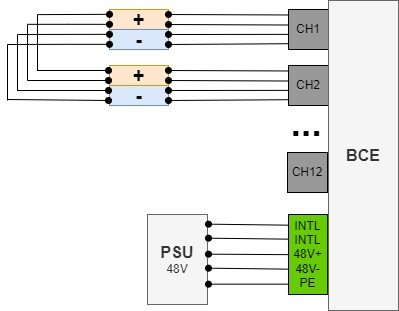

### Configuration

The Speedgoat real-time target machine communicates with the Speedgoat Battery Cell Emulator over EtherCAT. For this purpose, the Ethernet port of the target machine must be configured for EtherCAT.

Use a CAT5 cable or newer to connect the target machine and the BCE. On the target machine, choose an unused RJ45 Ethernet connector, an onboard interface or an IO71x/IO791 I/O module. Plug the other end of the cable into the upper RJ45 connector of the BCE, labeled with ETH1.

To activate EtherCAT support for the respective interface, enter the following in the MATLAB command window to open the Ethernet Configuration Tool:

Select **EtherCAT** in the **Configuration** column for the chosen interface, as shown below for the ETH1 interface:

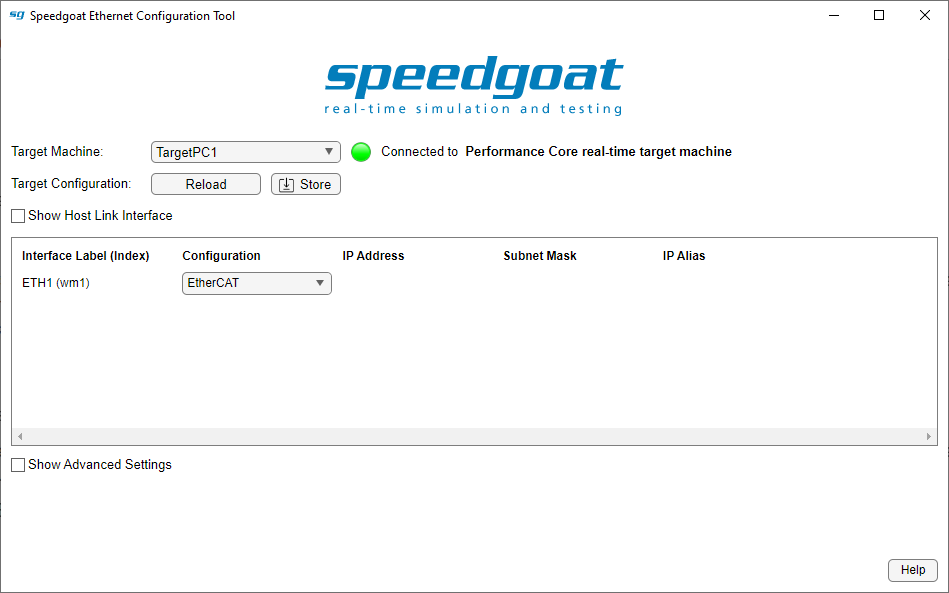

Click the **Store** button to store the configuration on the target machine, then close the Ethernet Configuration Tool when the process has finished.

## Open Simulink Model

 
modelName = 'sgMdl_BMTS_SimpleVoltageControlWithBCE';
open_system(modelName);         % Open Simulink model

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Open the Simulation Data Inspector
Simulink.sdi.view;

% Start the real-time application
tg.setStopTime(60);
tg.start;

% Wait for the application to stop
while(strcmp(tg.status, 'running'))
    pause(1);
end

% Select the signals for plotting, set the axis limits and line colors
Simulink.sdi.setSubPlotLayout(2,1);
sdiRunIDs = Simulink.sdi.getAllRunIDs;
sdiLatestRun = Simulink.sdi.Run.getLatest;
s = sdiLatestRun.getSignalsByName('V_Cell1'); s=s(1);
plotOnSubPlot(s,1,1,true);
s.LineColor = [0.6350 0.0780 0.1840];
s = sdiLatestRun.getSignalsByName('V_Cell2'); s=s(1);
plotOnSubPlot(s,1,1,true);
s.LineColor = [0.8500 0.3250 0.0980];
s = sdiLatestRun.getSignalsByName('I_Cell1'); s=s(1);
plotOnSubPlot(s,2,1,true);
s.LineColor = [0 0.4470 0.7410];
s = sdiLatestRun.getSignalsByName('I_Cell2'); s=s(1);
plotOnSubPlot(s,2,1,true);
s.LineColor = [0.4940 0.1840 0.5560];
Simulink.sdi.setSubplotLimits(1,1,'AllRange',[0,60,-1,6]);
Simulink.sdi.setSubplotLimits(2,1,'AllRange',[0,60,-2,2]);

### Check the Results

Open the Simulink scope connected to the [BMTS Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_read) block and compare the signals to check if the voltage control is working as expected. On the analog scope, the voltage as well as the current of cells 1 and 2 are displayed. The voltage of cell 1 increases from 0 V to 5 V between 10 s and 20 s of simulation time, while the voltage of cell 2 increases from 0 V to 4 V during the same time. 

If cells 1 and 2 are connected together, a current will start to flow from cell 1 to cell 2, due to the voltage difference and the current input to the Cell_2.I signal of the [BMTS Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_write) block. Both cells measure the 5 V potential driven by cell 1. To command the sink current in this way, the BCE is configured to operate in "Manual" current sink mode.

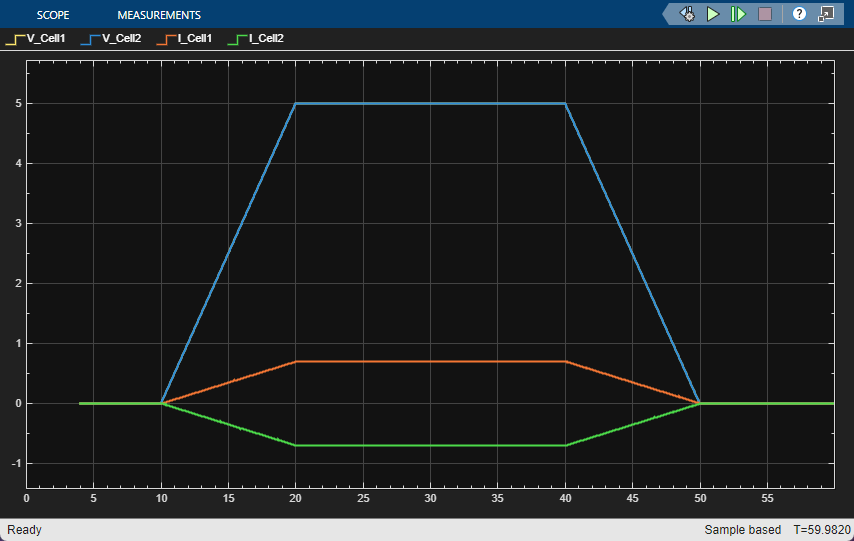

If cells 1 and 2 are not connected, no current will flow, and both cells measure their own voltage: 5 V for cell 1, and 4 V for cell 2 respectively.

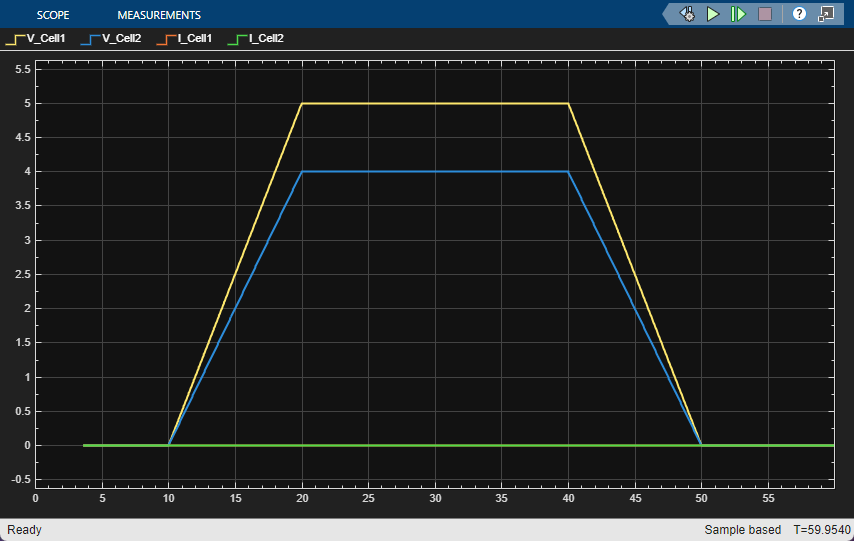

If "Automatic" current sink mode is selected in the [BMTS Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_setup) block (tab "BCE Device Configuration") and the two cells are connected, the current drawn by cell 2 will be determined automatically based on the difference between the cell's internal voltage and the externally applied voltage (in this case the voltage of cell 1).

## Additional References

- [BCE Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_usage_notes)